# Simulation

- runnare tantissimo

- animare drive per drive

- manna (stocasticità estraendo n_topple=4 randi sugli active sites e fare find(j==1) per nn_left etc)

- periodic boundary

save_to_file = true;

L = 50;
steps = 10e8;
wait = 10e3;


[event_size, z] = BTW(L,steps,wait);

if save_to_file; save(sprintf('BTW_data_%s.mat', datestr(now,'mm-dd_HH-MM')), "event_size"); end

# Post processing and plotting

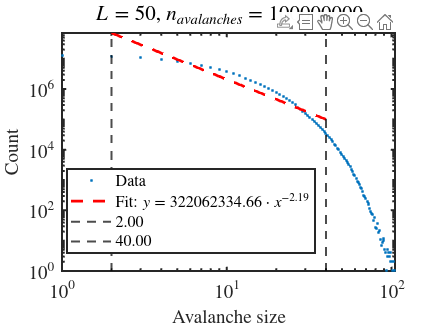

if ~exist('event_size','var'); load("/home/francesco/Documents/UNI/Sistemi complessi/SOC simulation/avalanche_data.mat"); end

[sizes, count] = postprocess_data(event_size);
title = "$L = "+L+"$, $n_{avalanches} = "+steps+"$";
[fig] = plot_avalanches(sizes,count,2,40,title);